# simulated ecg

f1 = figure('Name','60BPM NORMAL SINUS RHYTHM');
f2 = figure('Name','100BPM NORMAL SINUS RHYTHM');

2秒分(1000samples)のプロットを比較


x = linspace(0,1000,1000);

align data

y1 = sim060d3(10001:11000);
y2 = sim060f3(10063:11062);
y3 = sim060a3(9854:10853);
y4 = sim100d3(10001:11000);
y5 = sim100f3(9991:10990);
y6 = sim100a3(10061:11060);
%

レベルの違いを吸収するために正規化

y1 = normalize(y1);
y2 = normalize(y2);
y3 = normalize(y3);
y4 = normalize(y4);
y5 = normalize(y5);
y6 = normalize(y6);

plot

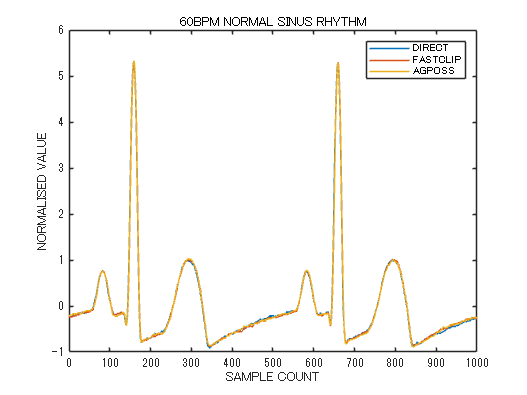

figure(f1);
plot(x, y1, x, y2, x, y3)
legend("DIRECT", "FASTCLIP", "AGPOSS");
xlabel("SAMPLE COUNT");
ylabel("NORMALISED VALUE");
title("60BPM NORMAL SINUS RHYTHM");

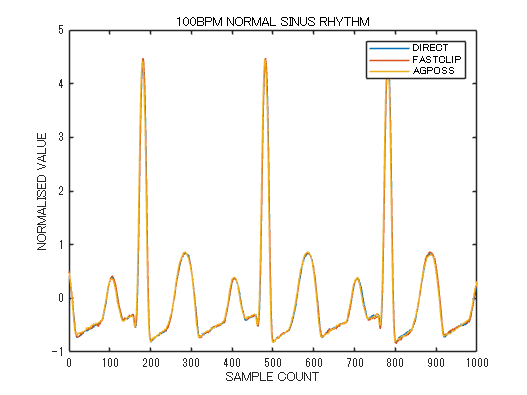

figure(f2);
plot(x, y4, x, y5, x, y6)
legend("DIRECT", "FASTCLIP", "AGPOSS");
xlabel("SAMPLE COUNT");
ylabel("NORMALISED VALUE");
title("100BPM NORMAL SINUS RHYTHM");

**correlation coefficients**

60BPM Direct / Fastclip

corrcoef(y1,y2)

ans =     1.0000    0.9969
    0.9969    1.0000


60BPM Direct / AGPoss

corrcoef(y1,y3)

ans =     1.0000    0.9983
    0.9983    1.0000


100BPM Direct / Fastclip

corrcoef(y4,y5)

ans =     1.0000    0.9991
    0.9991    1.0000


100BPM Direct / AGPoss

corrcoef(y4,y6)

ans =     1.0000    0.9915
    0.9915    1.0000
